# Construct a source consisting of a number of partials in form of sinus oscillators (at least 30). Add a vibrato modulation option. Arrange the partial amplitudes so that the spectrum slope becomes -6 dB/octave. The waveform should approach a sawtooth

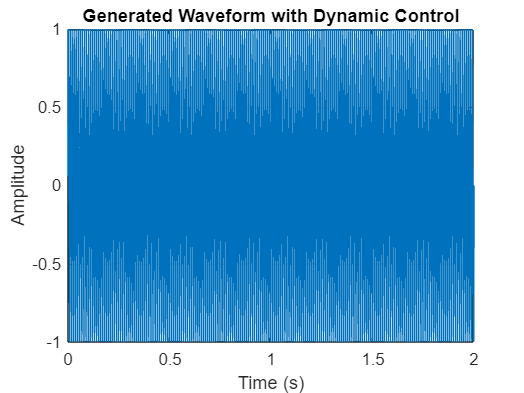

f_0 = 100; % Set up Fundamental frequency
num_partials = 30; % Set up Number of partials (at least 30)

% Use sawtooth_waveform_generate(f_0, num_partials) function to generate the waveform
sawtooth_waveform_generate(f_0, num_partials);

# Make at least 5 formant filters using resonance two-pole filters. Control the synthesis by specifying the logarithmic frequency in MIDI note number, the formant frequencies and bandwidths in Hertz.

fsamp = 32000;
midi_freqs = [54, 66, 73, 45, 24]; % Set up midi frequencies
format_bandwidths_hz = [25, 40, 60, 80, 100]; % Set up Format bandwidths in Hertz

% Use FiveFormatFilters_synthesis(midi_freqs, format_bandwidths_hz) function to synthesize suond
source_signal = FiveFormatFilters_synthesis(midi_freqs, format_bandwidths_hz);

% Play the synthesized sound:
a = audioplayer(source_signal, fsamp);
a.play;

# Add a control parameter for dynamics, which control both the sound level (in dB) and the spectral slope of the source (dB/octave).

fsamp = 32000;
midi_freqs = [54, 66, 73, 45, 24]; % Set up midi frequencies
format_bandwidths_hz = [25, 40, 60, 80, 100]; % Set up Format bandwidths in Hertz

% Control sound level and spectral slope parameters
level_dB = 0.5;
slope_dB_per_octave = 0.5;

% Play the synthesized voice
source_signal = AddControlParameters_synthesis(midi_freqs, format_bandwidths_hz, level_dB, slope_dB_per_octave);
a = audioplayer(source_signal, fsamp);
a.play;

# Test the model by inserting the measured values from the voice lab (or measure your voice again). Make a little melody with variation in pitch and vowel. Compare the result with the natural sound. Plot the result in a spectrogram.

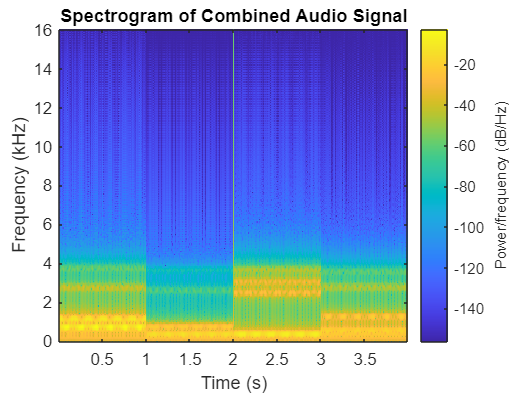

fsamp = 32000; % sampling rate
f_0 = 187.62; % fundamental frequency
totalTime = 1; % total time to synthesize
vibAmp = 0.001;
vibFreq = 6;
A = -0.8;

% Number of harmonics, staying below Nyquist
N_harmonics = floor(fsamp/(2*f_0));

% Spectrum slope parameter
a_slope = 0.6;
t = linspace(0.001, totalTime, totalTime*fsamp);
f_0vib = (1 + (vibAmp ./ t) .* sin(2*pi*vibFreq*t)) * f_0;

% Make the sine waves and add them together
p = zeros(size(t));
for i = 1 : N_harmonics
p = p + A*(i^(-a_slope))*sin(2*pi*i*f_0vib .* t);
end

fN = [712.26, 1154.41, 2760.24, 3735.94]; % as for the /a/ with singer's formant
fN2 = [336.64, 739.23, 2601.02, 3647.77]; % as for the /u/ with singer's formant
fN3 = [361.64, 2492.46, 3045.84, 3659.01]; % as for the /i/ with singer's formant
fN4 = [494.82, 1261.40, 2778.08, 3571.59]; % as for the /e/ with singer's formant
bN = [25, 40, 60, 80];

% Apply effect of formant bandwidths
qN = fN ./ bN;
qN2 = fN2 ./ bN;
qN3 = fN3 ./ bN;
qN4 = fN4 ./ bN;

% Compute the second order filter coefficients
T = 1/fsamp;
for i = 1 : 4
betas(i) = fN(i)*2*pi;
beta0s(i) = betas(i)*sqrt(1+1/(4*qN(i)^2));
alphas(i) = beta0s(i)/(2*qN(i));
aOnes(i) = -2*exp(-alphas(i)*T)*cos(betas(i)*T);
aTwos(i) = exp(-2*alphas(i)*T);
Gs(i) = 1 + aOnes(i) + aTwos(i);
end
for i = 1 : 4
betas2(i) = fN2(i)*2*pi;
beta0s2(i) = betas2(i)*sqrt(1+1/(4*qN2(i)^2));
alphas2(i) = beta0s2(i)/(2*qN2(i));
aOnes2(i) = -2*exp(-alphas2(i)*T)*cos(betas2(i)*T);
aTwos2(i) = exp(-2*alphas2(i)*T);
Gs2(i) = 1 + aOnes2(i) + aTwos2(i);
end
for i = 1 : 4
betas3(i) = fN3(i)*2*pi;
beta0s3(i) = betas3(i)*sqrt(1+1/(4*qN3(i)^2));
alphas3(i) = beta0s3(i)/(2*qN3(i));
aOnes3(i) = -2*exp(-alphas3(i)*T)*cos(betas3(i)*T);
aTwos3(i) = exp(-2*alphas3(i)*T);
Gs3(i) = 1 + aOnes3(i) + aTwos3(i);
end
for i = 1 : 4
betas4(i) = fN4(i)*2*pi;
beta0s4(i) = betas4(i)*sqrt(1+1/(4*qN4(i)^2));
alphas4(i) = beta0s4(i)/(2*qN4(i));
aOnes4(i) = -2*exp(-alphas4(i)*T)*cos(betas4(i)*T);
aTwos4(i) = exp(-2*alphas4(i)*T);
Gs4(i) = 1 + aOnes4(i) + aTwos4(i);
end

% Apply to "p" the desired number of resonances, in series.
% The recursive filter formula is
% Yn = G*X(n) - aOne*Y(n-1) - aTwo*Y(n-2)
pOut = p;
pOut(1) = 0.0;
pOut(2) = 0.0;
for j = 1 : 4
   for n = 3 : length(pOut)
       pOut(n) = Gs(j)*pOut(n) - aOnes(j)*pOut(n-1) - aTwos(j)*pOut(n-2);
   end
end
pOut2 = p;
pOut2(1) = 0.0;
pOut2(2) = 0.0;
for j = 1 : 4
   for n = 3 : length(pOut2)
       pOut2(n) = Gs2(j)*pOut2(n) - aOnes2(j)*pOut2(n-1) - aTwos2(j)*pOut2(n-2);
   end
end
pOut3 = p;
pOut3(1) = 0.0;
pOut3(2) = 0.0;
for j = 1 : 4
   for n = 3 : length(pOut3)
       pOut3(n) = Gs3(j)*pOut3(n) - aOnes3(j)*pOut3(n-1) - aTwos3(j)*pOut3(n-2);
   end
end
pOut4 = p;
pOut4(1) = 0.0;
pOut4(2) = 0.0;
for j = 1 : 4
   for n = 3 : length(pOut4)
       pOut4(n) = Gs4(j)*pOut4(n) - aOnes4(j)*pOut4(n-1) - aTwos4(j)*pOut4(n-2);
   end
end

volume = 0.5;
ca = [pOut, pOut2, pOut3, pOut4];
a = audioplayer(ca*volume, fsamp);
a.play;

figure;
spectrogram(ca, hann(256), 128, 512, fsamp, 'yaxis');
title('Spectrogram of Combined Audio Signal');